**1. Control System Tuner**

open_system('GrindingRobot')

Setup the paramter for Grinding System

Ts = 0.1;
Tf = 10;

run('../config.m')

Tune the system using Control System Tuner

controlSystemTuner("ControlSystemTunerSession")

After executing the script, navigate to the "Tuning" tab and select "Tune" to begin the tuning process

% blockPath = 'GrindingRobot/PID Controller';
% 
% % Get parameters
% Kp = get_param(blockPath, 'P');
% Ki = get_param(blockPath, 'I');
% 
% fprintf('PI Gains:\nKp = %s\nKi = %s', Kp, Ki);

% Kp_CST = 1.25; % this is taken from the tuner session
% Ki_CST = 1.25e-07;
Kp_CST = 5.98; 
Ki_CST = 8.16e-07;

**2. RL tuner **

Load the Simulink model that integrates the reinforcement learning environment, configure the observation and action space dimensions, and set a fixed random seed to ensure consistent results across runs.

mdl = 'rlgrindingsystemPIDTune';
open_system(mdl)

[env,obsInfo,actInfo] = localCreatePIDEnv(mdl);
numObs = prod(obsInfo.Dimension);
numAct = prod(actInfo.Dimension);

rng(0)

Set up the actor neural network

initialGain = single([1e-7 1e-3 2]);

actorNet = [
    featureInputLayer(numObs)
    fullyConnectedPILayer(initialGain,'ActOutLyr')
    ];

actorNet = dlnetwork(actorNet);

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

Define critic networks

criticNet = localCreateCriticNetwork(numObs,numAct);

critic1 = rlQValueFunction(initialize(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic2 = rlQValueFunction(initialize(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic = [critic1 critic2];

Define the training options and train the agent

initialLR = 1e-3;

actorOpts = rlOptimizerOptions( ...
    LearnRate=initialLR, ...
    GradientThreshold=1);

criticOpts = rlOptimizerOptions( ...
    LearnRate=initialLR, ...
    GradientThreshold=1);

agentOpts = rlTD3AgentOptions(...
    SampleTime=Ts,...
    MiniBatchSize=128, ...
    ExperienceBufferLength=1e7,...
    ActorOptimizerOptions=actorOpts,...
    CriticOptimizerOptions=criticOpts);

agentOpts.TargetPolicySmoothModel.StandardDeviation = sqrt(0.1);

% create agent 
agent = rlTD3Agent(actor,critic,agentOpts);


% trainOpts = rlTrainingOptions(...
%     MaxEpisodes=250, ...
%     MaxStepsPerEpisode=ceil(Tf/Ts), ...
%     Plots="training-progress", ...
%     Verbose=false);

trainOpts = rlTrainingOptions(...
    MaxEpisodes=250, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    StopTrainingCriteria="AverageReward", ...
    StopTrainingValue=-50, ...
    Plots="training-progress", ...
    Verbose=false);

trainingStats1 = train(agent, env, trainOpts);
save('agent_checkpoint_episode300.mat', 'agent');

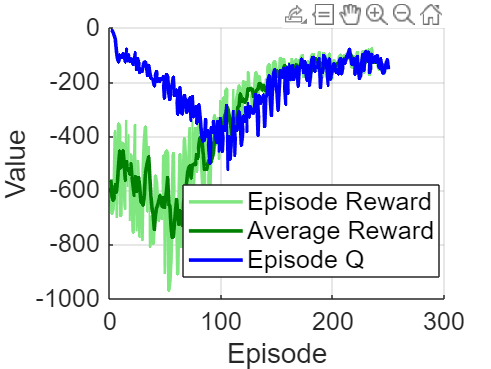

episodeReward = trainingStats1.EpisodeReward;
episodeQ = trainingStats1.EpisodeQ0;
averageReward = trainingStats1.AverageReward;

episodes = 1:length(episodeReward);

figure;
hold on;
plot(episodes, episodeReward, 'Color', [0.5 0.9 0.5], 'DisplayName', 'Episode Reward', 'LineWidth', 2);           
plot(episodes, averageReward, 'Color', [0 0.5 0], 'DisplayName', 'Average Reward', 'LineWidth', 2); 
plot(episodes, episodeQ, 'b', 'DisplayName', 'Episode Q', 'LineWidth', 2);                                       

fontSize = 14;
xlabel('Episode', 'FontSize', fontSize);
ylabel('Value', 'FontSize', fontSize);
legend('Location', 'best', 'FontSize', fontSize);
grid on;
set(gca, 'FontSize', fontSize); 
hold off;

Evaluation

simOpts = rlSimulationOptions(MaxSteps=maxsteps);
experiences = sim(env,agent,simOpts);

actor = getActor(agent);
parameters = getLearnableParameters(actor);

% Ki = abs(parameters{1}(1))
% Kp = abs(parameters{1}(2))
Kd = abs(parameters{1}(1))
Ki = abs(parameters{1}(2))
Kp = abs(parameters{1}(3))

mdlTest = 'GrindingRobot';
open_system(mdlTest); 
set_param([mdlTest '/PID Controller'],'P',num2str(Kp))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki))
sim(mdlTest)

rlStep = simout;
rlCost = cost;
rlStabilityMargin = localStabilityAnalysis(mdlTest);

set_param([mdlTest '/PID Controller'],'P',num2str(Kp_CST))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki_CST))
sim(mdlTest)
cstStep = simout;
cstCost = cost;
cstStabilityMargin = localStabilityAnalysis(mdlTest);

Compare 2 approaches

figure
plot(cstStep)
hold on
plot(rlStep)
grid on
legend('Control System Tuner','RL',Location="southeast")
title('Step Response')

rlStepInfo = stepinfo(rlStep.Data,rlStep.Time);
cstStepInfo = stepinfo(cstStep.Data,cstStep.Time);
stepInfoTable = struct2table([cstStepInfo rlStepInfo]);
stepInfoTable = removevars(stepInfoTable,{'SettlingMin', ...
    'TransientTime','SettlingMax','Undershoot','PeakTime'});
stepInfoTable.Properties.RowNames = {'CST','RL'};
stepInfoTable

stabilityMarginTable = struct2table( ...
    [cstStabilityMargin rlStabilityMargin]);
stabilityMarginTable = removevars(stabilityMarginTable,{...
    'GMFrequency','PMFrequency','DelayMargin','DMFrequency'});
stabilityMarginTable.Properties.RowNames = {'CST','RL'};
stabilityMarginTable

rlCumulativeCost  = sum(rlCost.Data)
cstCumulativeCost = sum(cstCost.Data)